### 3. Haga uso de las funciones del RVC para hallar la cinemática inversa de su robot asignado y compruebe los resultados del punto anterior. Ya que existen varias funciones en el *Toolbox *explique:

### ¿Cuál es la diferencia entre estas funciones?

- ikine6s: cinemática inversa para robot de revolución de muñeca esférica de 6 ejes.

- ikine: cinemática inversa mediante método numérico iterativo.

- ikunc: cinemática inversa con optimización.

- ikcon: cinemática inversa usando optimización con límites de articulación.

- ikine_sym: cinemática inversa analítica obtenida simbólicamente.

### ¿Cuál debe usar para su robot y por qué? (Revise la documentación del *Toolbox*)  

# RVC toolbox: ikine6s

q = R.ikine6s (T) son las coordenadas conjuntas (1xN) correspondientes a la pose T del efector final del robot representada por una transformada homogénea SE (3) (4x4). Esta es una solución analítica para un robot de 6 ejes con muñeca esférica (la forma más común de brazos de robot industrial).

Si T representa una trayectoria (4x4xM), entonces se calcula la cinemática inversa para todas las M poses, lo que da como resultado q (MxN) y cada fila representa los ángulos de articulación en la pose correspondiente.

q = R.IKINE6S (T, config) como arriba pero especifica la configuración del brazo en forma de una cadena que contiene uno o más de los códigos de configuración:

'l': brazo a la izquierda (predeterminado)

'r': brazo a la derecha

'u': codo hacia arriba (predeterminado)

'd': codo hacia abajo

'n': muñeca no volteada (predeterminado)

'f': muñeca volteada (girada 180 grados)

### Conclusión

Dado que el robot ABB CRB 15000 no tiene muñeca esférica sino con offset, esta función no se puede utilizar para realizar la cinemática inversa.

# RVC toolbox: ikine

Este método se puede utilizar para robots con 6 o más grados de libertad. 

q = R.ikine (T) son las coordenadas conjuntas (1xN) correspondientes a la pose del efector final del robot T (4x4) que es una transformaciónhomogénea.

q = R.ikine (T, q0, options) especifica la estimación inicial de las coordenadas conjuntas.

En todos los casos, si T es 4x4xM, se toma como una secuencia de transformada homogénea y R.ikine () devuelve las coordenadas conjuntas correspondientes a cada una de las transformadas en la secuencia. q es MxN donde N es el número de articulaciones del robot. La estimación inicial de q para cada paso de tiempo se toma como la solución del paso de tiempo anterior.

**Options**

'pinv': usa el pseudo-inverso en lugar de la transposición jacobiana (predeterminado)

'ilimit', L: establece el recuento máximo de iteraciones (predeterminado 1000)

'tol', T: establece la tolerancia en la norma de error (predeterminado 1e-6)

'alpha', A: establece la ganancia de tamaño de paso (predeterminado 1)

'varstep': habilita el tamaño de paso variable si pinv es falso

'verbose': muestra el número de iteraciones para cada punto

'verbose = 2': muestra el estado en cada iteración

'plot': plotea el estado de iteración frente al tiempo

clc
syms theta_1 theta_2 theta_3 theta_4 theta_5 theta_6  
L1=0.265; L2=0.444; L3=0.110; L4=0.470; L5=0.080; L6=0.037;

L(1) = Link('revolute','alpha', 0,    'a', 0,   'd',L1,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(2) = Link('revolute','alpha', -pi/2,    'a', 0,   'd',0,   'offset', -pi/2,   'modified', 'qlim',[-pi pi]);
L(3) = Link('revolute','alpha', 0,    'a', L2,   'd',0,   'offset', 0,   'modified', 'qlim',[-3.92699 1.48353]);
L(4) = Link('revolute','alpha', -pi/2,    'a', L3,   'd',L4,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(5) = Link('revolute','alpha', pi/2,    'a', 0,   'd',0,   'offset', 0,   'modified', 'qlim',[-pi pi]);
L(6) = Link('revolute','alpha', -pi/2,    'a', L5,   'd',L6,   'offset', 0,   'modified', 'qlim',[-pi pi]);
% Se articulan todos los links y se le asigna un nombre a todo el sistema
Robot_ABB = SerialLink(L,'name','ABB CRB 15000'); 

qSolve = Robot_ABB.ikine(Target,[0 0 0 0 0 0],[1 1 1 1 1 1]); 	%inverse kinematics using iterative numerical method


q1 = qSolve(1)*(180/pi)

q1 = 1.1252e+05

q2 = qSolve(2)*(180/pi)

q2 = -110.8511

q3 = qSolve(3)*(180/pi)

q3 = 27.4054

q4 = qSolve(4)*(180/pi)

q4 = -2.5674e+05

q5 = qSolve(5)*(180/pi)

q5 = 4.0833e+04

q6 = qSolve(6)*(180/pi)

q6 = -42.1526

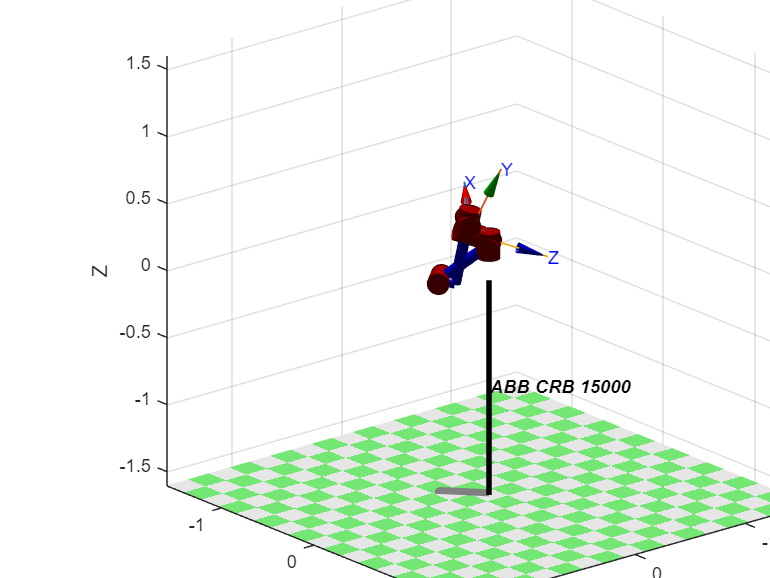

Robot_ABB.plot([q1 q2 q3 q4 q5 q6],'workspace',[-0.5 0.5 -0.5 0.5 -0.1 1],'scale',0.5,'noa', 'view',[140 20])

Robot_ABB.fkine([q1 q2 q3 q4 q5 q6])

ans =    -0.5743   -0.1259   -0.8089    0.0907
   -0.7644    0.4363    0.4748   -0.1106
    0.2931    0.8910   -0.3468    0.3397
         0         0         0    1.0000


### Conclusión

Se observa que la solución no convergue, se intento aumentar el número de iteraciones pero tampoco se logró. Por lo cual se descarta este método para resolver la cinemática inversa de nuestro robot.